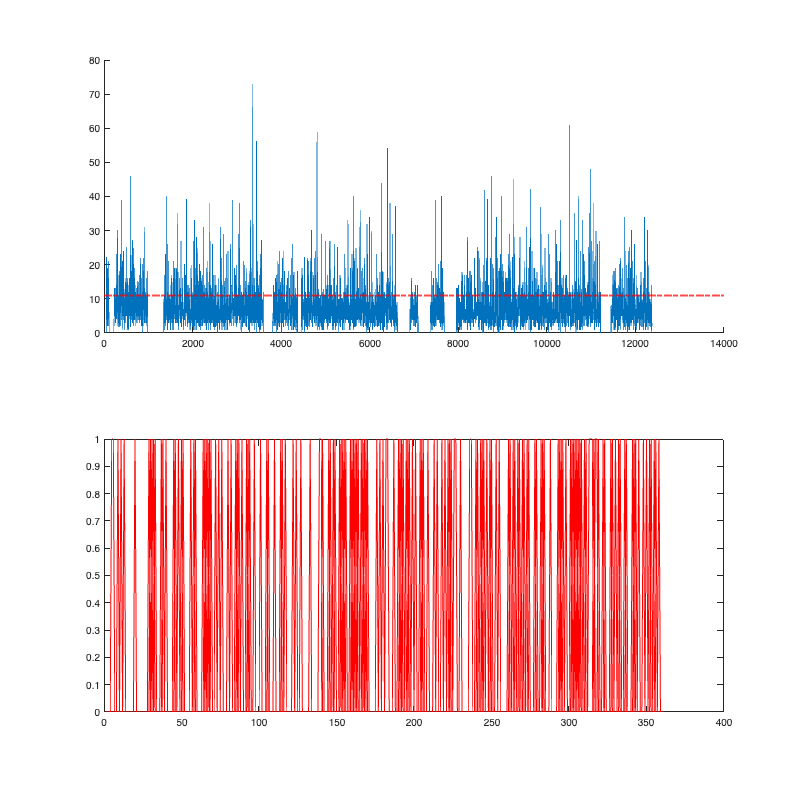

figure
plot (MAct)
yline(sce_n_cells_threshold,'-.r','LineWidth',2);
box off

subplot(2,1,2)
    % for i = 1:length(TRace)
    %     line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
    % end
    for i=1 :nbassemblies

        plot(CellCl(i,:),'Color','red')
        hold on
    end
    hold off



% Create color map for different cell colors
colorMap = lines(nbassemblies);

% Plot raster plot
figure;
hold on;

for i = 1:nbassemblies
    % Find indices of spikes for the current cell
    % [trialIndices, spikeIndices] = find(spikeData(:, i, :));
    
    % Plot spikes for the current cell with the corresponding color
    tmp=CellCl(i,:);
    t=linspace(1,length(CellCl),length(CellCl));
    bar(t,tmp+i-1);
    hold on
end
hold off

% Customize the plot
% xlabel('Time');
% ylabel('Trial');
% title('Raster Plot of Neuronal Activity');
% colormap(colorMap);
% colorbar('Ticks', linspace(0, 1, numCells), 'TickLabels', 1:numCells);
% xlim([0, maxSpikesPerTrial]);
% ylim([1, numTrials]);

idortho=cellfun(@length,assemblyortho)

imagesc(Tr1b(assemblyortho{1},:));

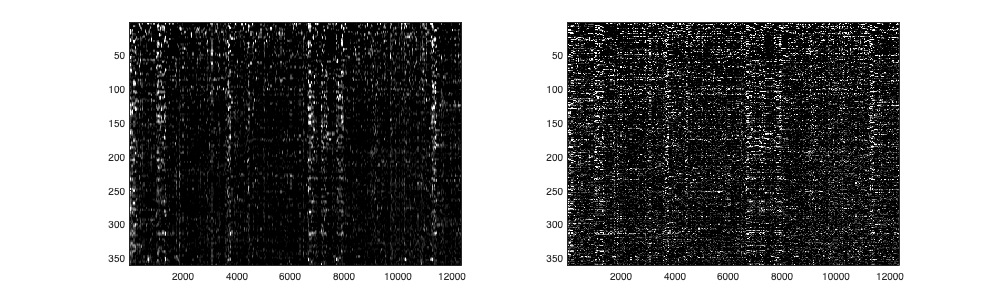

%raw image cells not sorted
smtrace=smoothdata(Tr1b,1,'gaussian',5);
smtrace=smoothdata(smtrace,2,'gaussian',5);
subplot(1,2,1)
imagesc(smoothdata(smtrace))
colormap gray
clim ([0 0.2])
subplot(1,2,2)
imagesc(Tr1b)
colormap gray
clim ([0 0.2])
%tightfig(gcf)
set(gcf, 'Position', [0, 0, 1000, 300]);


%axis image
% hold on
% Y=zeros(1,length(TRace))-10;
%     for i = 1:length(TRace)
%         % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
%         line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g','LineWidth',0.2);
%         %text(TRace(i),1,'*','FontSize',20);
%     end
%     hold off

TSNE=tsne(Tr1b,"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",30,"Distance","correlation");
[B , index]=sort(TSNE);


imagesc(Tr1b(index,:))
colormap gray
clim ([0 0.3])

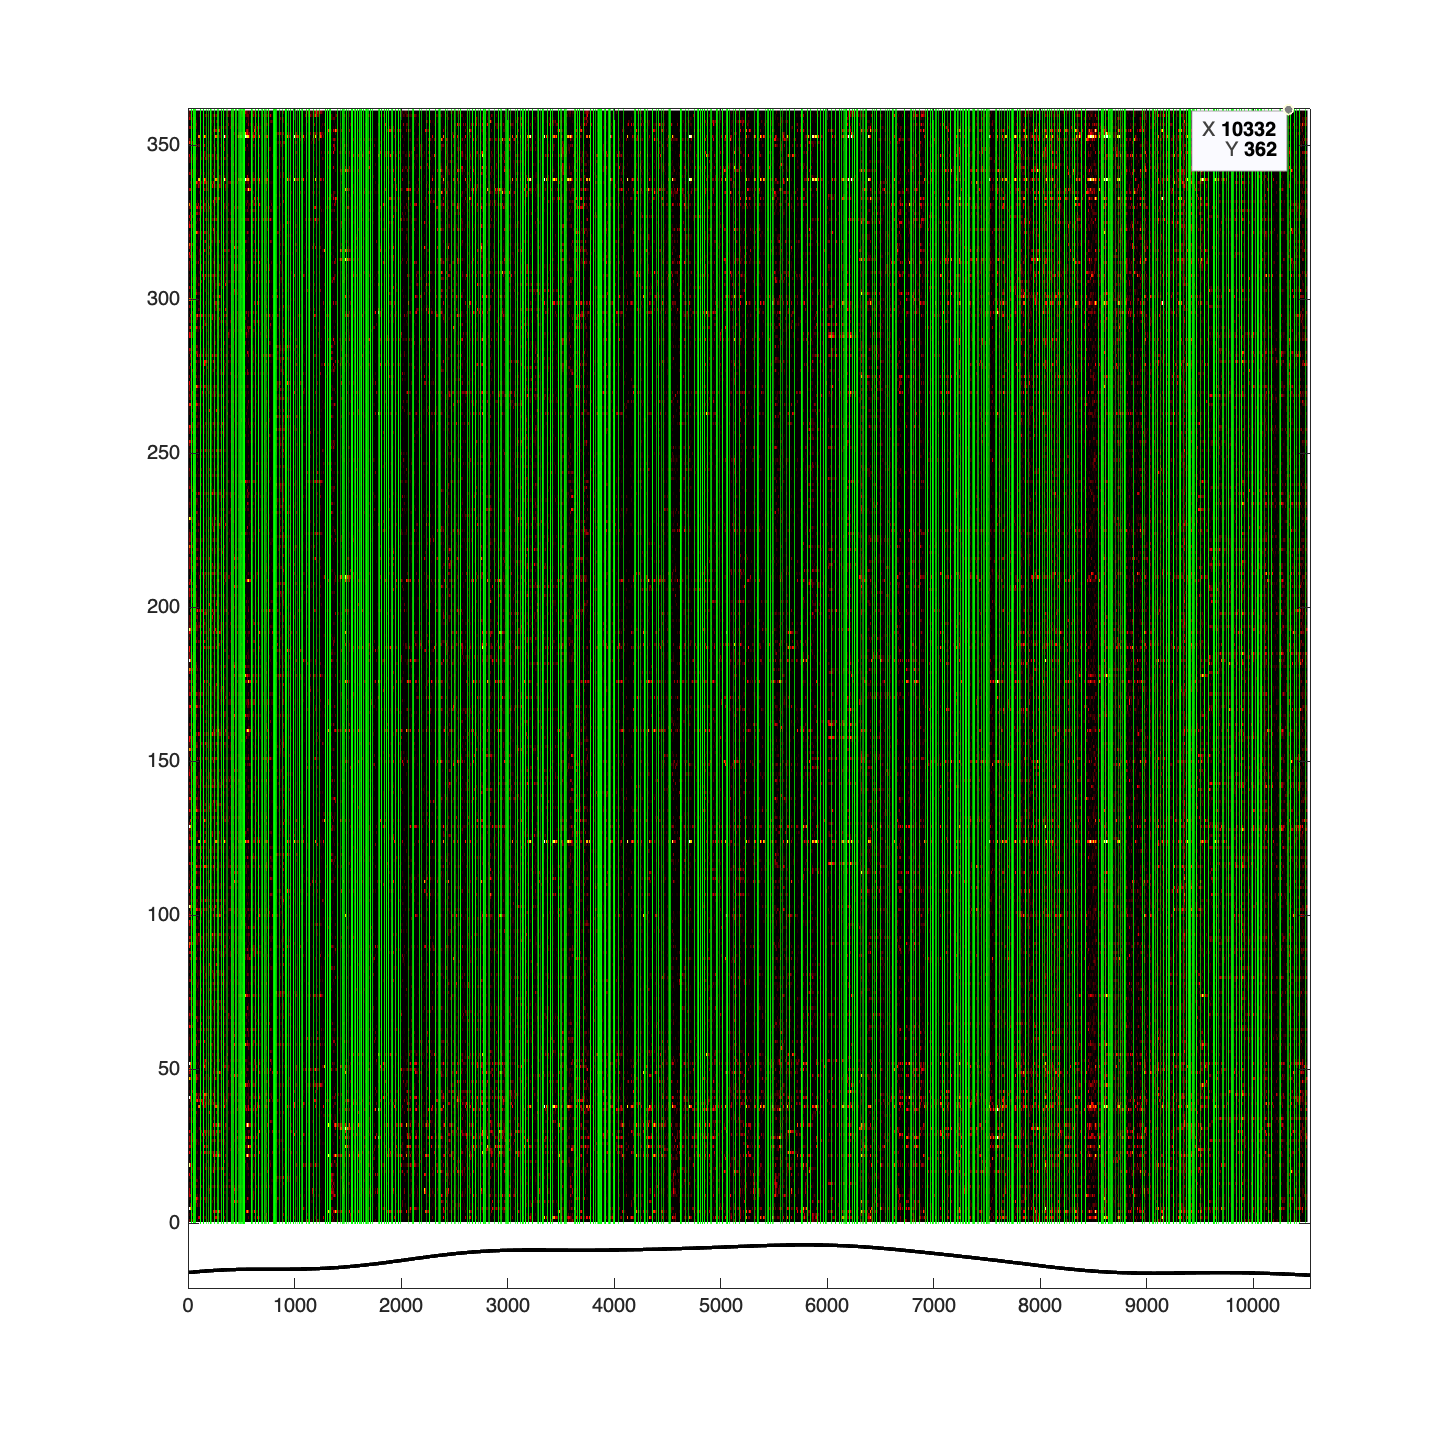

%raster cells tSNE sorted
TSNE=tsne(Tr1b,"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
    "Distance","correlation",'Perplexity',50,'Exaggeration',20);
[B , index]=sort(TSNE);
%raster t-sne all trace
figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
smtrace=smoothdata(smtrace,2,'gaussian',5);

imagesc(smtrace(index,:))
colormap hot
axis xy
clim ([0 0.3])
hold on
plot (speedraw-20,'Color','k','LineWidth',2)
hold off
set(gcf, 'Position', [0, 0, 1000, 1000]);
axis ([0 Nz -21 NCell])
hold on
for i = 1:length(TRace)
    % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
    line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g','LineWidth',0.2);
    %text(TRace(i),1,'*','FontSize',20);
end

hold off

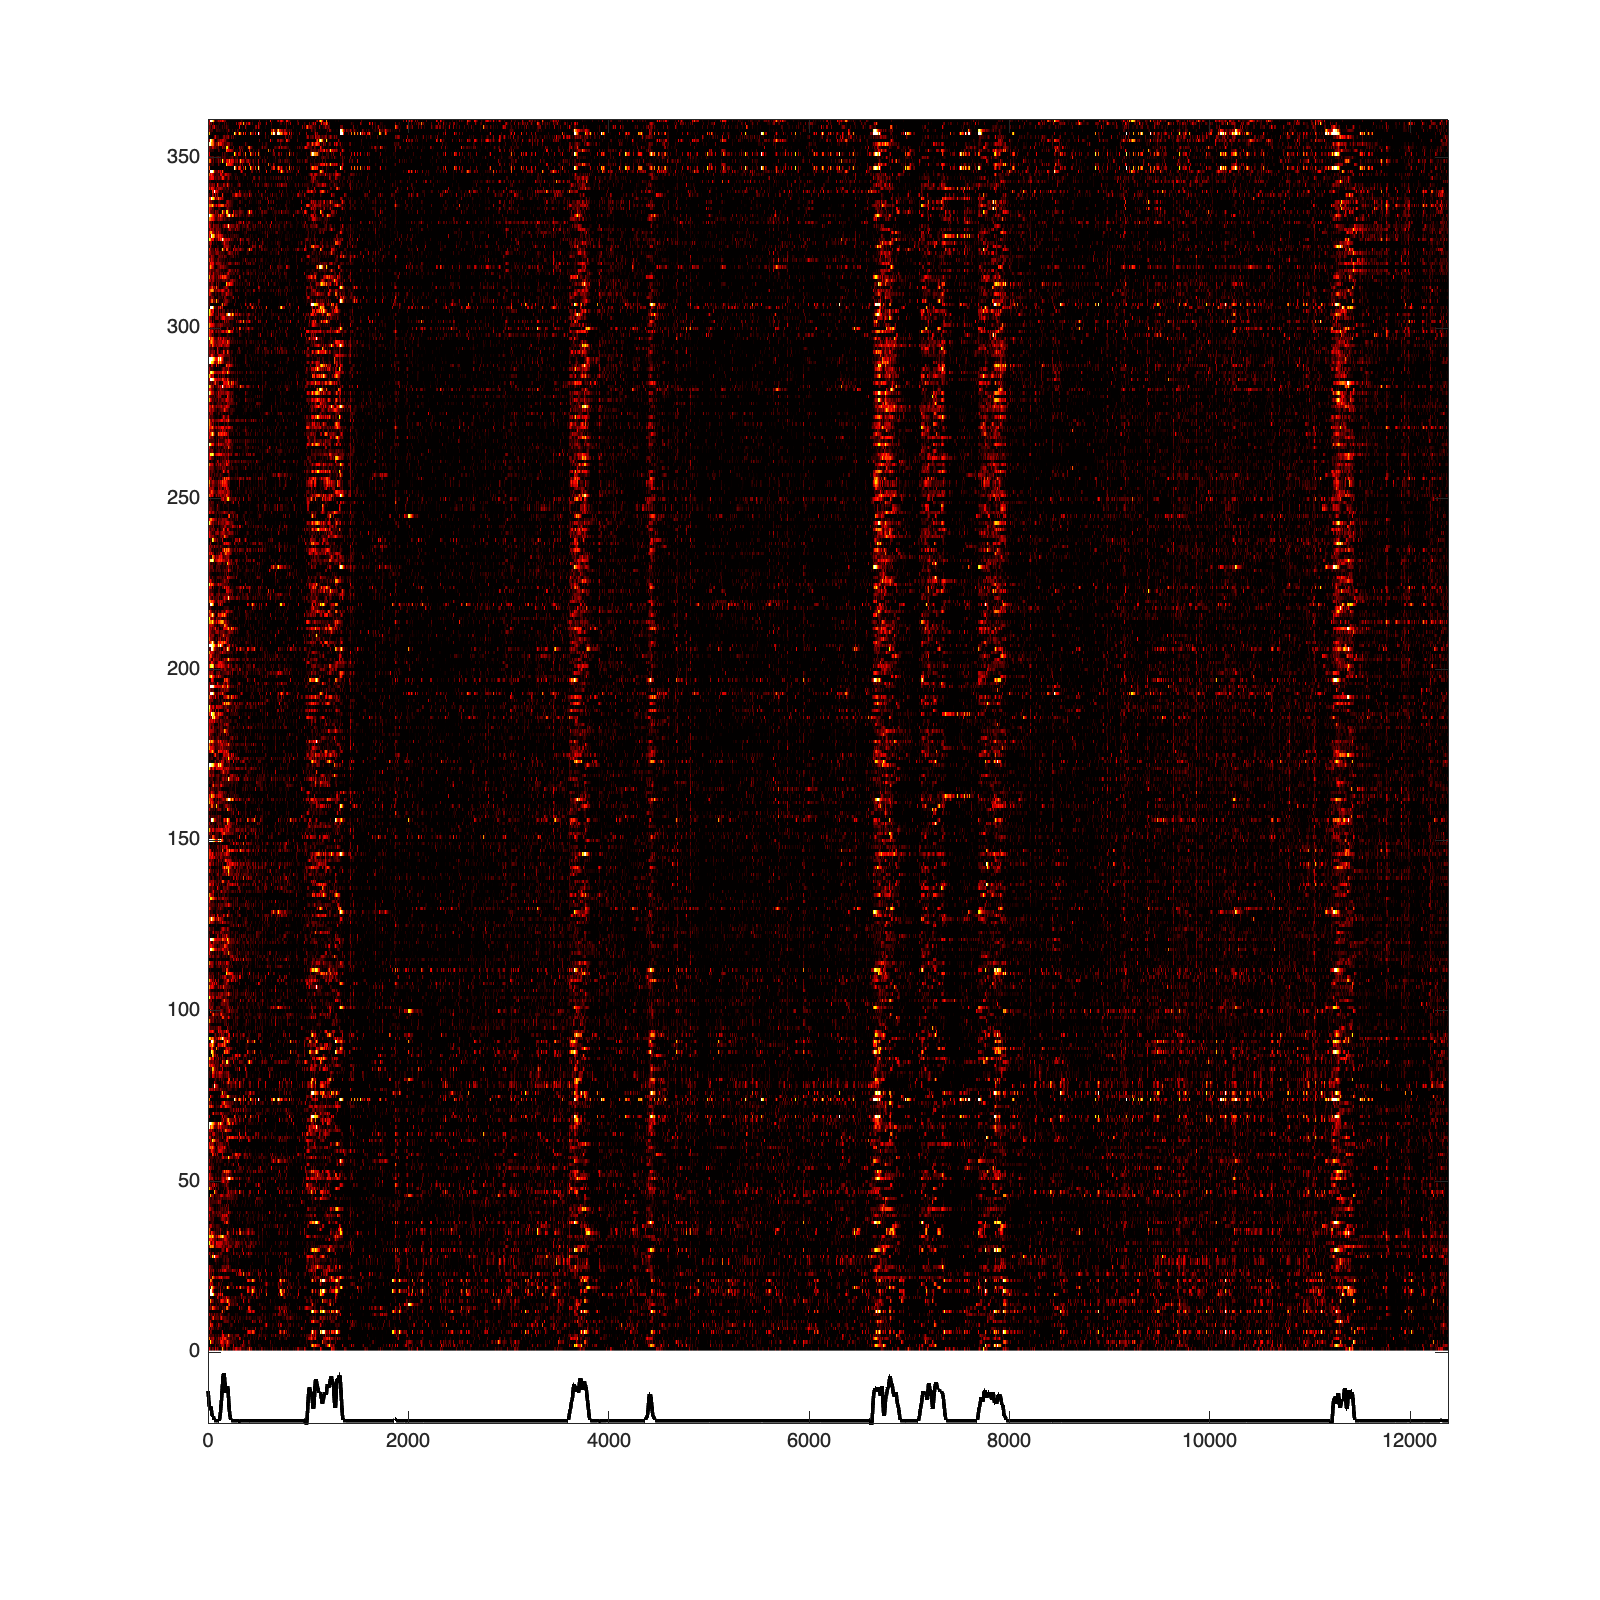

%raster cells tSNE sorted rest period
TSNE=tsne(Tr1b(:,WinRest),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
    "Distance","correlation",'Perplexity',50,'Exaggeration',20);
[B , index]=sort(TSNE);

figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace(index,:))

colormap hot
axis xy
clim ([0 0.3])
hold on
plot (speedraw-20,'Color','k','LineWidth',2)
hold off
set(gcf, 'Position', [0, 0, 1000, 1000]);
axis ([0 Nz -21 NCell])

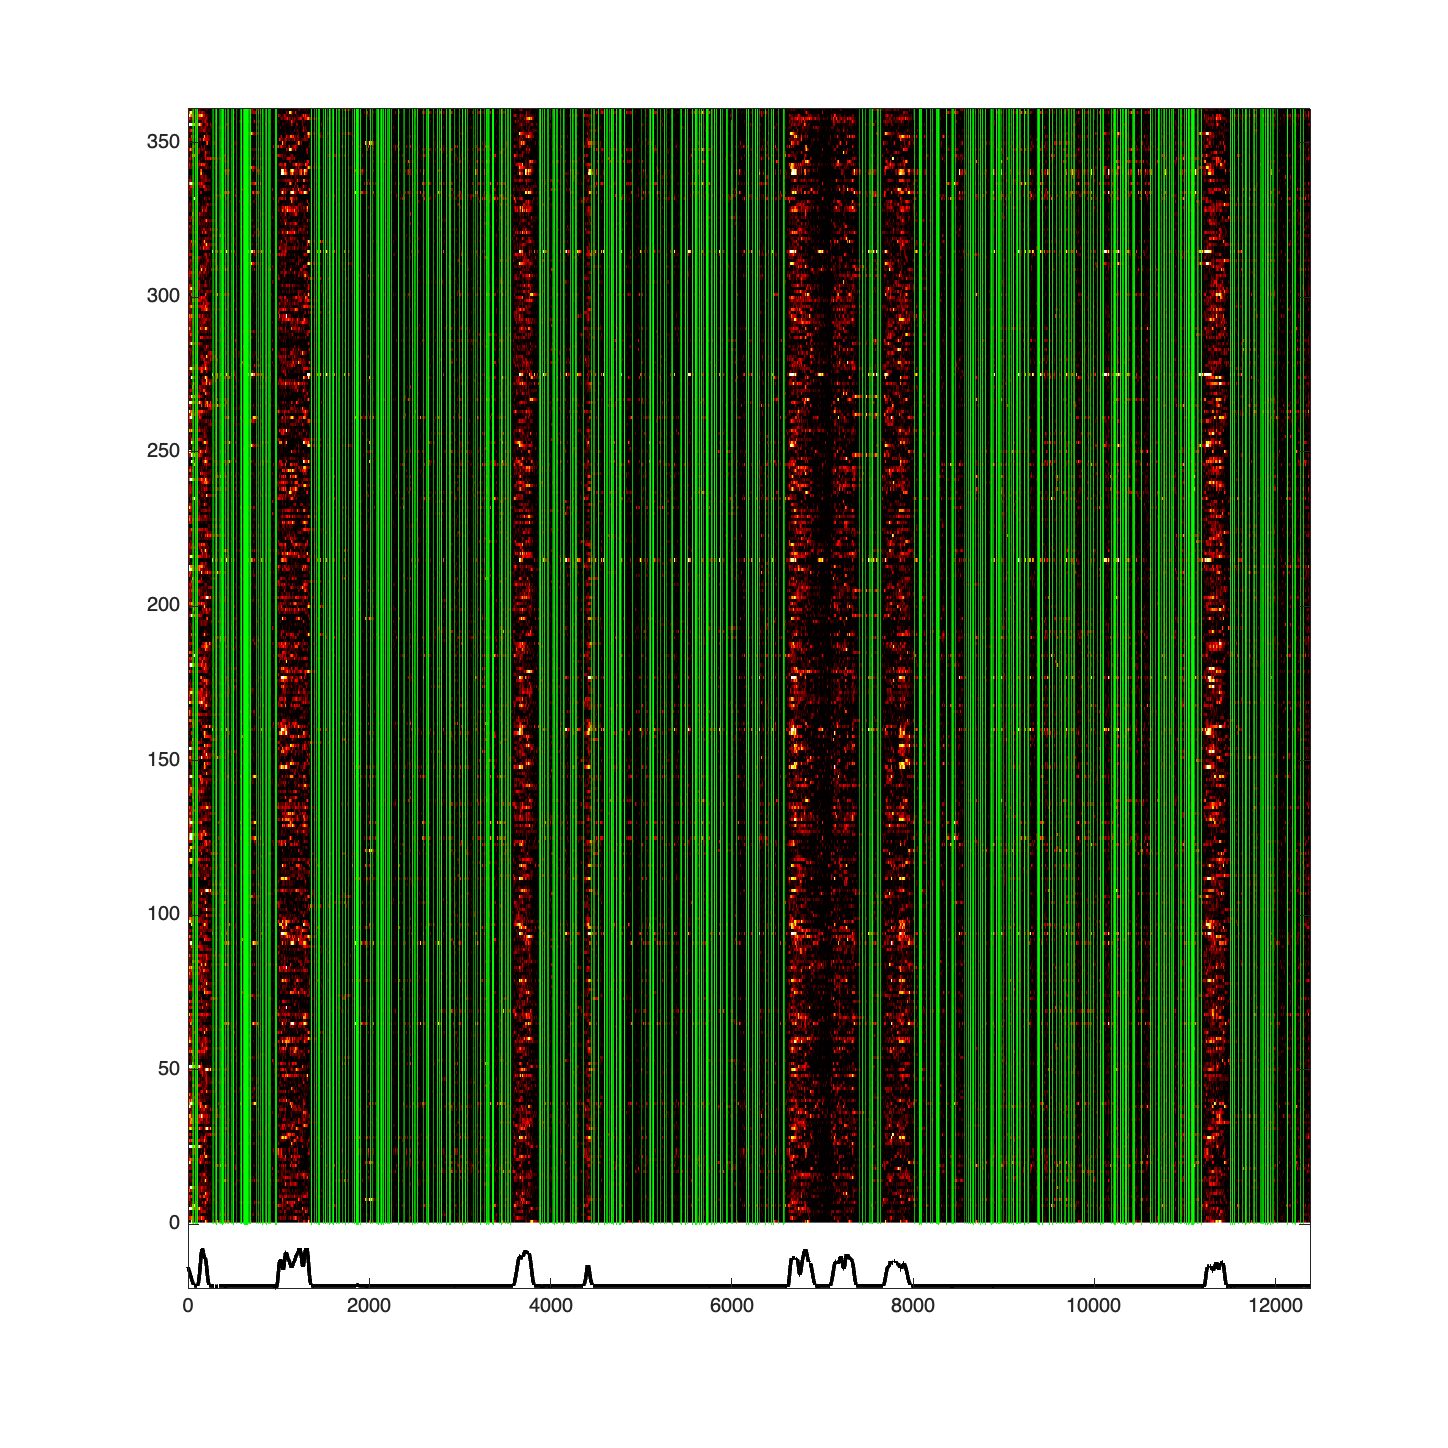

%raster cells tSNE sorted run period
TSNE=tsne(Tr1b(:,WinActive),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
    "Distance","correlation",'Perplexity',4,'Exaggeration',100);
[B , index]=sort(TSNE);
%figure;scatter(TSNE(:,1),TSNE(:,2),'DisplayName','TSNE')
figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace(index,:))

colormap hot
axis xy
clim ([0 0.3])
hold on
plot (speed-20,'Color','k','LineWidth',2)
hold off
set(gcf, 'Position', [0, 0, 1000, 1000]);
axis ([0 Nz -21 NCell])
hold on
for i = 1:length(TRace)
    % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
    line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g','LineWidth',0.1);
    %text(TRace(i),1,'*','FontSize',20);
end

hold off

UMAP & UST (v4.4), Herzenberg Lab, Stanford University,
	Original inventors: Leland McInnes, John Healy & James Melville
	MATLAB/C++/Java/Python implementors/evolvers: Connor Meehan, Jonathan Ebrahimian & Stephen Meehan

ans =
	javahandle_withcallbacks.edu.stanford.facs.swing.ImageButton
Parallelizing UMAP with MATLAB's 16 assigned logical cores for nn_descent_tasks, sgd_tasks


 Running basic (ub) reduction, v4.4
(ub=basic, us=supervised, ubt=template, ust=supervised template)


min=-11.50, max=1.50
mins:	-0.25289     -0.2626    -0.29811    -0.29403    -0.20525    -0.24279    -0.24123    -0.22966    -0.30218    -0.27458    -0.42952    -0.23938     -0.1316    -0.23882    -0.35337     -0.1624     -0.2481    -0.28433    -0.19131    -0.16383    -0.13723    -0.24047    -0.22978    -0.29059    -0.23587    -0.23273    -0.24189    -0.24912    -0.27992    -0.11632    -0.22696    -0.25379    -0.18876    -0.23495    -0.18561    -0.23256    -0.21266    -0.14202    -0.24786    -0.24884    -0.20477    -0.21624    -0.22317    -0.16702     -0.1334    -0.22646    -0.25006    -0.31824    -0.24392    -0.20546    -0.29548    -0.18494    -0.10234    -0.20651    -0.17462    -0.24119    -0.18023    -0.16448    -0.21499    -0.18863    -0.38338     -0.1667    -0.17421    -0.17902    -0.17355    -0.23763    -0.15351    -0.17639    -0.14535    -0.19462    -0.33296    -0.18894    -0.21181    -0.18503    -0.18995    -0.20925    -0.18177    -0.26094    -0.16254    -0.19348    -0.25911    -

ans =   Contour with properties:

    EdgeColor: [0.5000 0.5000 0.6000]
    LineStyle: '-'
    LineWidth: 1
    FaceColor: 'none'
    LevelList: [0.0013 0.0021 0.0030 0.0042 0.0056 0.0074 0.0092 0.0110 0.0132 0.0171]
        XData: [256×256 double]
        YData: [256×256 double]
        ZData: [256×256 double]

  Show all properties

UMAP reduction finished (cost 8.77 secs)
 Finished basic (ub) reduction


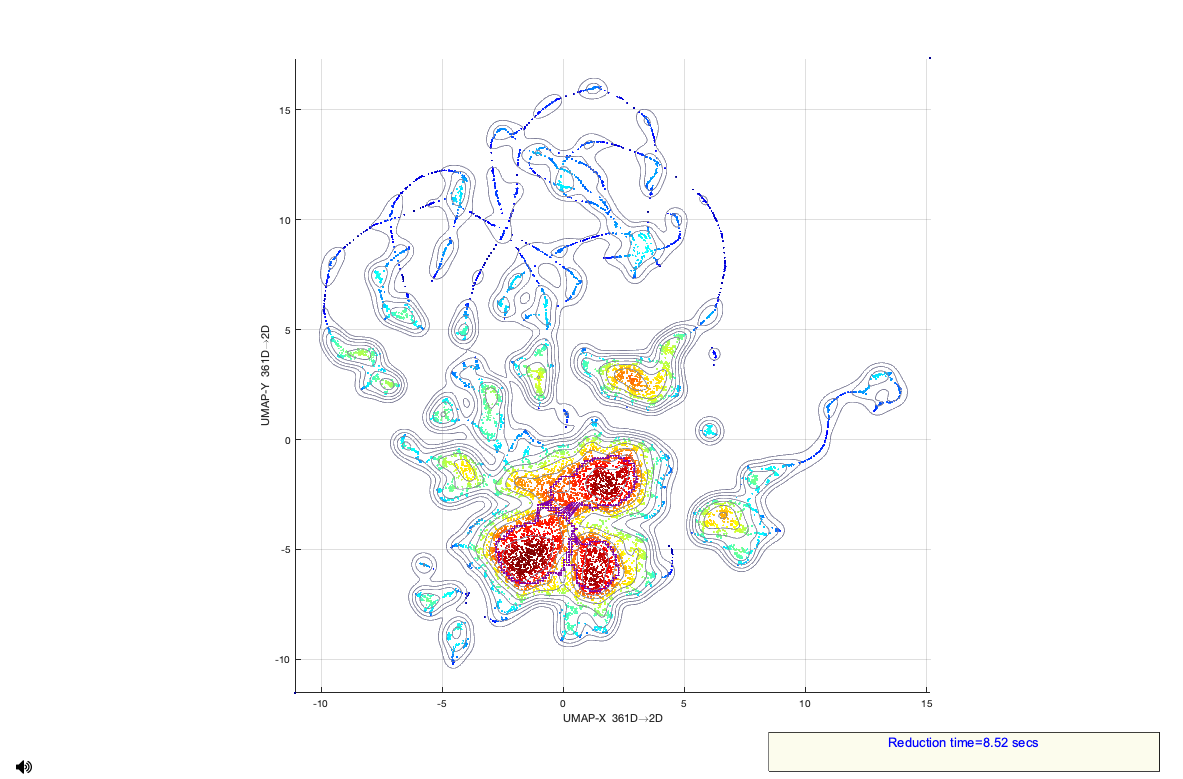

%raster cells tSNE sorted run period
[reduction, umap, clusterIdentifiers, extras]=run_umap(transpose(Tr1b));


[B , index]=sort(TSNE);

figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace(index,:))

colormap hot
axis xy
clim ([0 0.3])
hold on
plot (speedraw-20,'Color','k','LineWidth',2)
hold off
set(gcf, 'Position', [0, 0, 1000, 1000]);
axis ([0 Nz -21 NCell])

%raster tsne running period
% TSNE=tsne(Tr1b(:,WinActive),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
%     "Distance","correlation",'Perplexity',50,'Exaggeration',20);
%[B , index]=sort(TSNE);
[coeff,score,latent,~,explained,~]=pca(transpose(Tr1b(:,WinActive)));
[B , index]=sort(coeff(:,1));

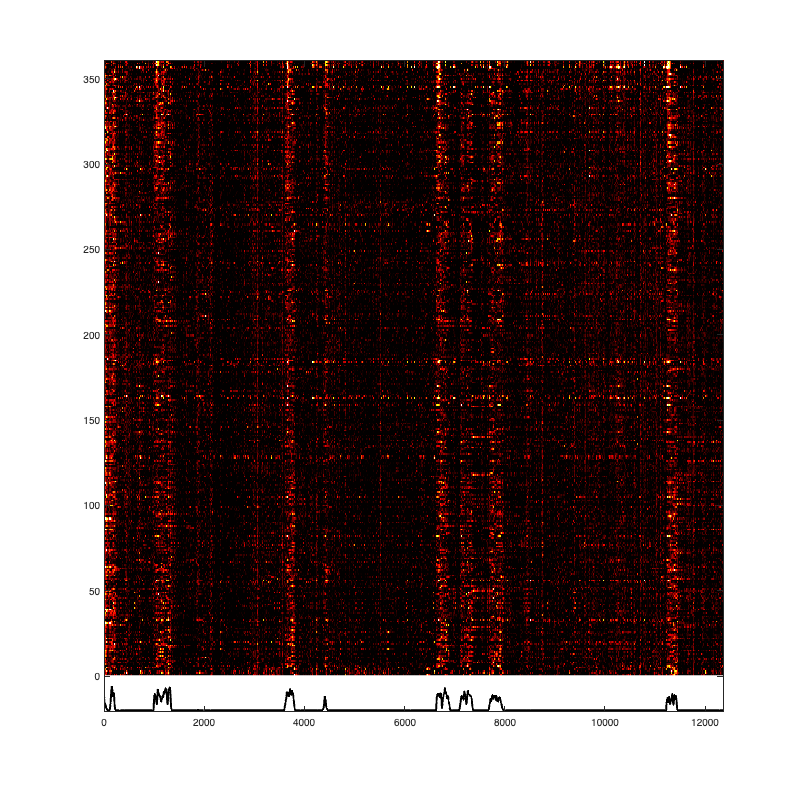

%raster PCA 1
figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
%smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace(index,:))
colormap hot
axis xy
clim ([0 0.3])
hold on
plot (speedraw-20,'Color','k','LineWidth',2)
hold off
set(gcf, 'Position', [0, 0, 1000, 1000]);
axis ([0 Nz -21 NCell])

highspeed=find (speedraw>=1);
lowspeed=find (speedraw<1);
for n=1:length(speedraw)
    if speedraw(n)>1
        testspeed(n)=1;
    else
        testspeed(n)=0;
    end
end

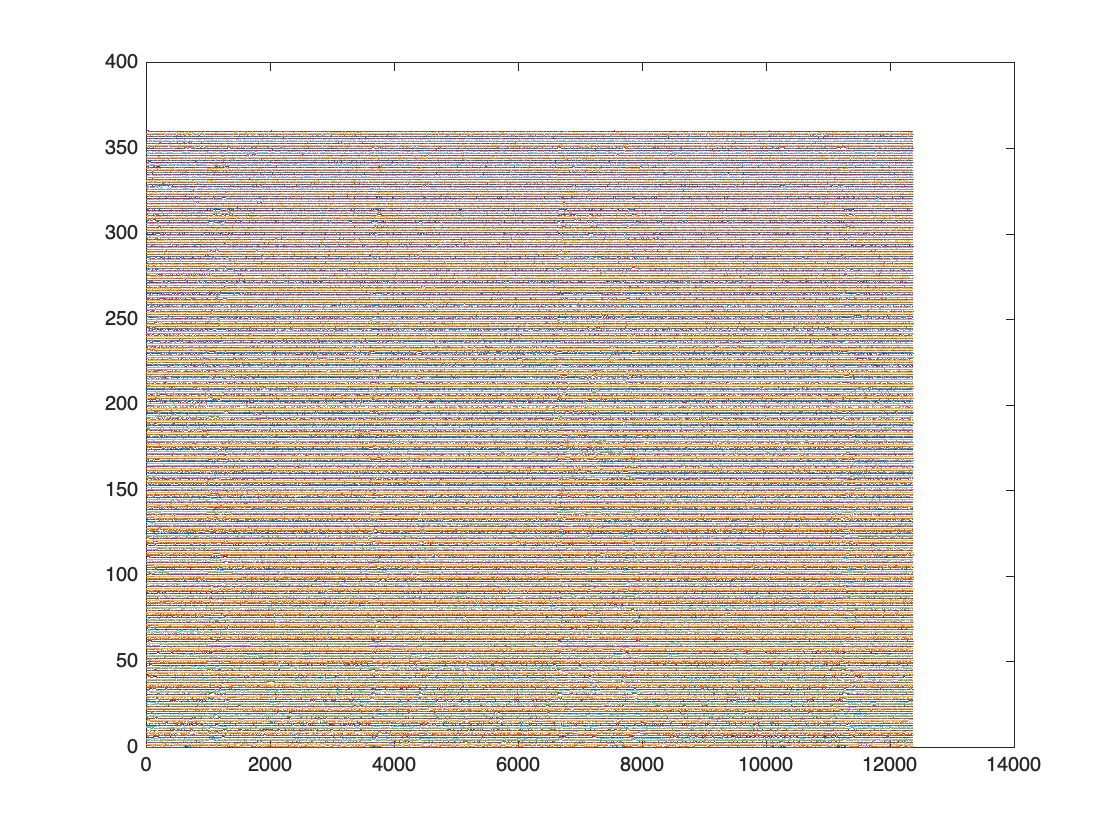

figure
for i = 1:NCell
    % Raster(i,Acttmp2{i}) = 1;           %Raster = real raster of cell activity
    plot(MovT,Tr1b(i,:)+i-1)
    hold on
    %plot(MovT(Acttmp2{i}),Tr1b(i,Acttmp2{i})+i-1,'.r')
end

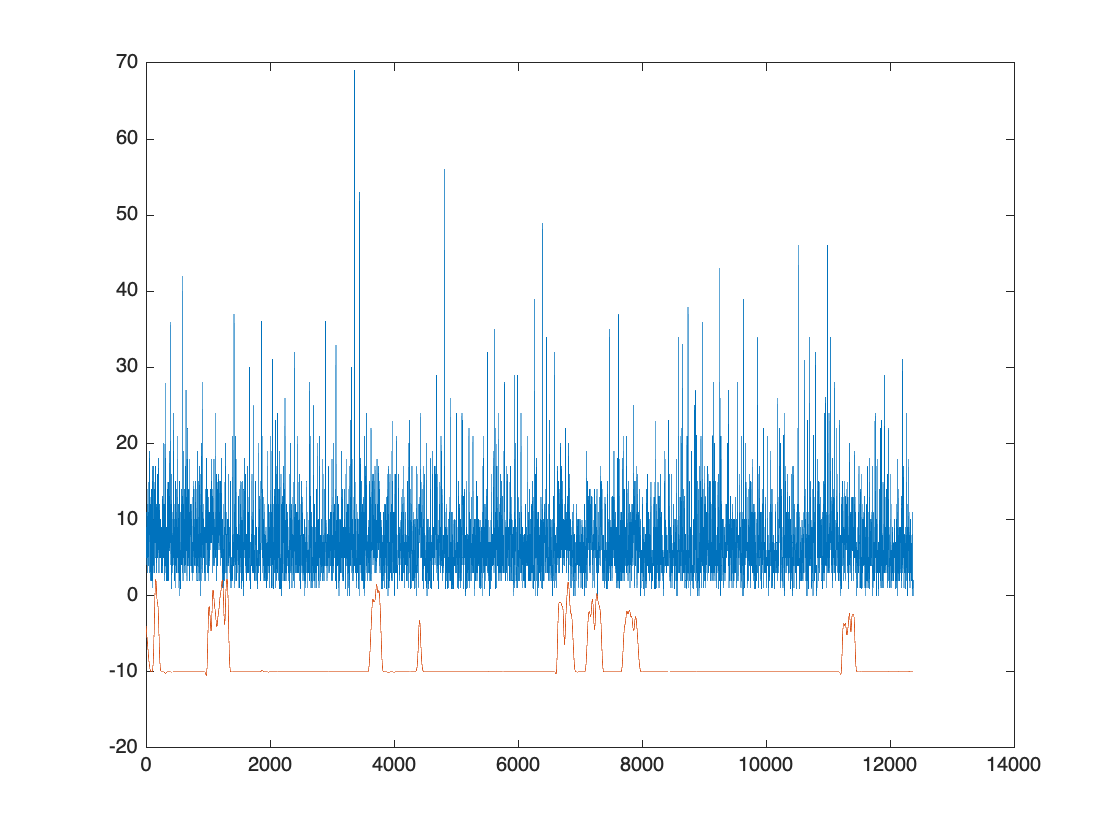

figure 
plot (MAct)
hold on 
plot(speed-10)